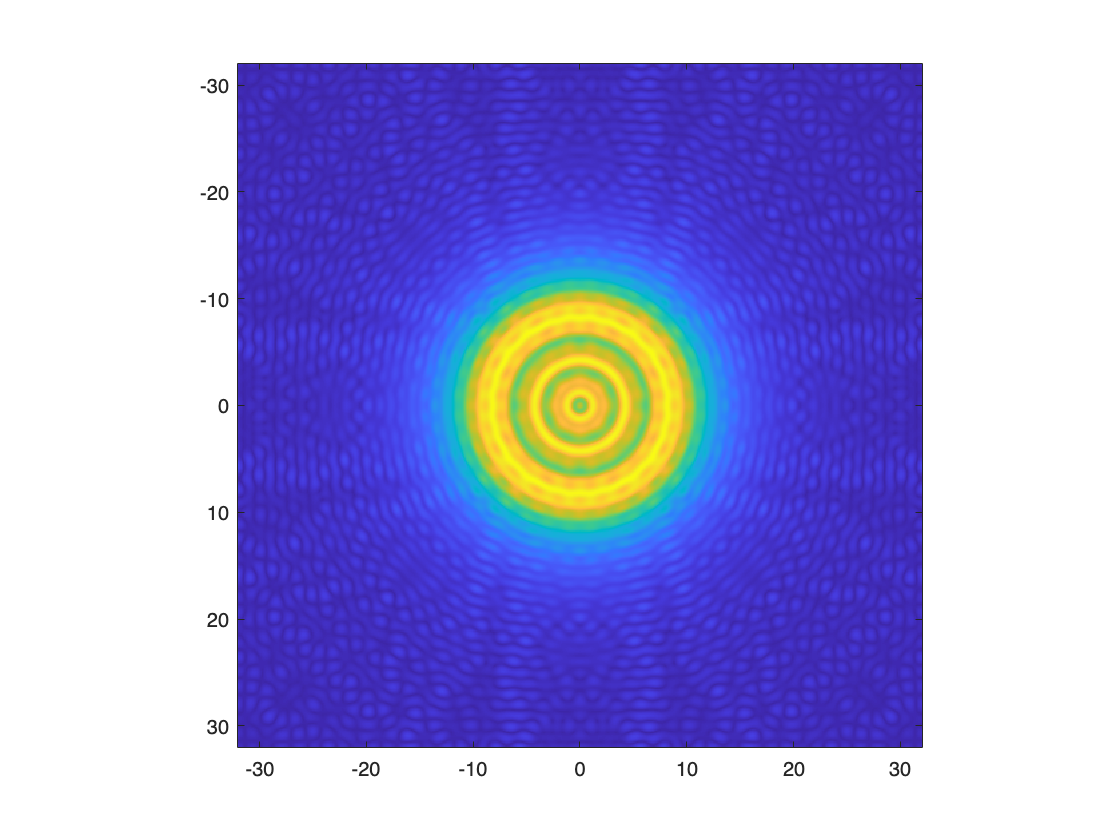

% Probe parameters
cnvangle = 20; % mrad
energy = 200; % keV
k = energy*0.05067730942*sqrt(1+1021.997855/energy); % 1/A
lambda = 2*pi/k; % A

% Compute parameters
range = 64;
kpixel = 8;
x = -range/2:1/kpixel:range/2;
y = x;
[kx,ky] = meshgrid(-kpixel/2:1/range:kpixel/2, -kpixel/2:1/range:kpixel/2);

% Multislice paramters
dz = 1; % A
thetax = 0; % mrad
thetay = 0; % mrad

% Create probe and propagator
probek = sqrt(kx.^2+ky.^2);
probek(probek>cnvangle*k/1000)=0;
probek(probek>0)=1;

propagator = exp(-1i*pi*(kx.^2+ky.^2)*lambda*dz+2*pi*1i*(kx*tan(thetax)+ky*tan(thetay))*dz);

% WIP
for i=1:100
    probek = probek.*propagator;
end

probe = fftshift(fft2(probek));
imagesc(x,y,abs(probe))
pbaspect([1 1 1]);